# PHASE 5 — Runtime / Time Complexity Comparison

clear; clc; close all;

% Add full src directory
addpath(genpath("./src"));

% Directories
dataDir = "./data/raw/";
outDir  = "./results/";
if ~exist(outDir, 'dir')
    mkdir(outDir);
end

% Load files
files = ["t1_icbm_normal_1mm_pn3_rf0.nii", ...
         "t1_icbm_normal_1mm_pn5_rf0.nii", ...
         "t1_icbm_normal_1mm_pn9_rf0.nii"];

% Load clean image
clean = niftiread(fullfile(dataDir, "t1_icbm_normal_1mm_pn0_rf0.nii"));
clean = mat2gray(double(clean(:,:,round(end/2))));

slice_idx = round(size(clean,1)/2);

% MAIN LOOP

R = [];   % results table rows

for i = 1:length(files)

    fname = files(i);
    disp("Processing " + fname);

    vol_noisy = niftiread(fullfile(dataDir, fname));
    noisy_slice_raw = double(vol_noisy(:,:,slice_idx));
    noisy_norm = mat2gray(noisy_slice_raw);

    % SPATIAL FILTER TIMING 

    f_gauss  = @() imgaussfilt(noisy_norm, 1.2);
    f_median = @() medfilt2(noisy_norm, [5 5]);
    f_wien   = @() wiener2(noisy_norm, [5 5]);
    f_nlm    = @() imnlmfilt(noisy_norm, ...
                    "SearchWindowSize",11, ...
                    "ComparisonWindowSize",3, ...
                    "DegreeOfSmoothing",1);

    % adaptive filter params
    f_adapt = @() adaptive_hybrid_filter(noisy_norm, 5, 1.2, 1.2);

    % bilateral params
    f_bilat = @() bilateral_hybrid_filter(noisy_slice_raw, 5, 35, 0.01);

    t_gauss = runtime_timer(f_gauss);
    t_median = runtime_timer(f_median);
    t_wien = runtime_timer(f_wien);
    t_nlm = runtime_timer(f_nlm);
    t_adapt = runtime_timer(f_adapt);
    t_bilat = runtime_timer(f_bilat);

    % FREQ-DOMAIN FILTER TIMING

    F = fftshift(fft2(noisy_norm));
    [M,N] = size(noisy_norm);
    [u,v] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);
    D = sqrt(u.^2 + v.^2);
    D0 = 30;

    f_ideal  = @() ifft2(ifftshift( ideal_lpf(D,D0) .* F ));
    f_butt   = @() ifft2(ifftshift( butterworth_lpf(D,D0,2) .* F ));
    f_gaussF = @() ifft2(ifftshift( gaussian_lpf(D,D0) .* F ));

    % wiener freq domain
    S_clean  = fftshift(fft2(clean));
    S_power  = abs(S_clean).^2;
    noise_var = var(noisy_norm(:) - clean(:));
    H_wiener = wiener_filter(S_power, noise_var);
    f_wienF  = @() ifft2(ifftshift(H_wiener .* F));

    t_ideal  = runtime_timer(f_ideal);
    t_buttF  = runtime_timer(f_butt);
    t_gaussF = runtime_timer(f_gaussF);
    t_wienF  = runtime_timer(f_wienF);


    % Store rows
    noiseLevel = extractAfter(fname, "_1mm_");   % e.g., "pn5_rf0.nii"

    R = [R;
        {fname, "Gaussian (Spatial)",   t_gauss};
        {fname, "Median",               t_median};
        {fname, "Wiener (Spatial)",     t_wien};
        {fname, "NLM",                  t_nlm};
        {fname, "Adaptive Hybrid",      t_adapt};
        {fname, "Bilateral Hybrid",     t_bilat};

        {fname, "Ideal LPF",            t_ideal};
        {fname, "Butterworth LPF",      t_buttF};
        {fname, "Gaussian LPF",         t_gaussF};
        {fname, "Wiener (Freq)",        t_wienF};
    ];

end

Processing t1_icbm_normal_1mm_pn3_rf0.nii
Processing t1_icbm_normal_1mm_pn5_rf0.nii
Processing t1_icbm_normal_1mm_pn9_rf0.nii


% Convert to table + save CSV

T5 = cell2table(R, ...
    "VariableNames", ["NoiseFile","Filter","Runtime_ms"]);

writetable(T5, fullfile(outDir, 'metrics', "phase5_runtime_metrics.csv"));

disp("Phase 5 completed — runtime table saved.");

Phase 5 completed — runtime table saved.


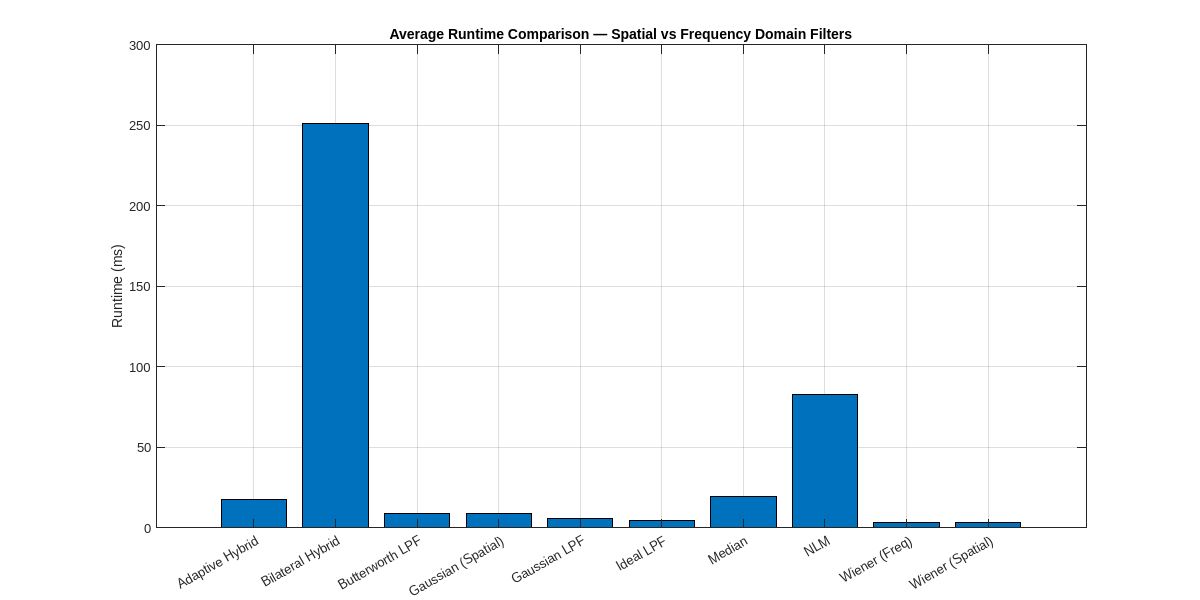

% BAR PLOT (Combined – All filters averaged)

% average runtime per filter across noise levels
filters = unique(T5.Filter);

avg_runtime = zeros(length(filters),1);

for k = 1:length(filters)
    avg_runtime(k) = mean(T5.Runtime_ms(strcmp(T5.Filter, filters(k))));
end

figure('Position',[200 200 1200 600]);
bar(avg_runtime);
set(gca, 'XTickLabel', filters, 'XTickLabelRotation', 30);
ylabel("Runtime (ms)");
title("Average Runtime Comparison — Spatial vs Frequency Domain Filters");
grid on;

saveas(gcf, fullfile(outDir, 'figures', 'phase5', "runtime_barplot.png"));

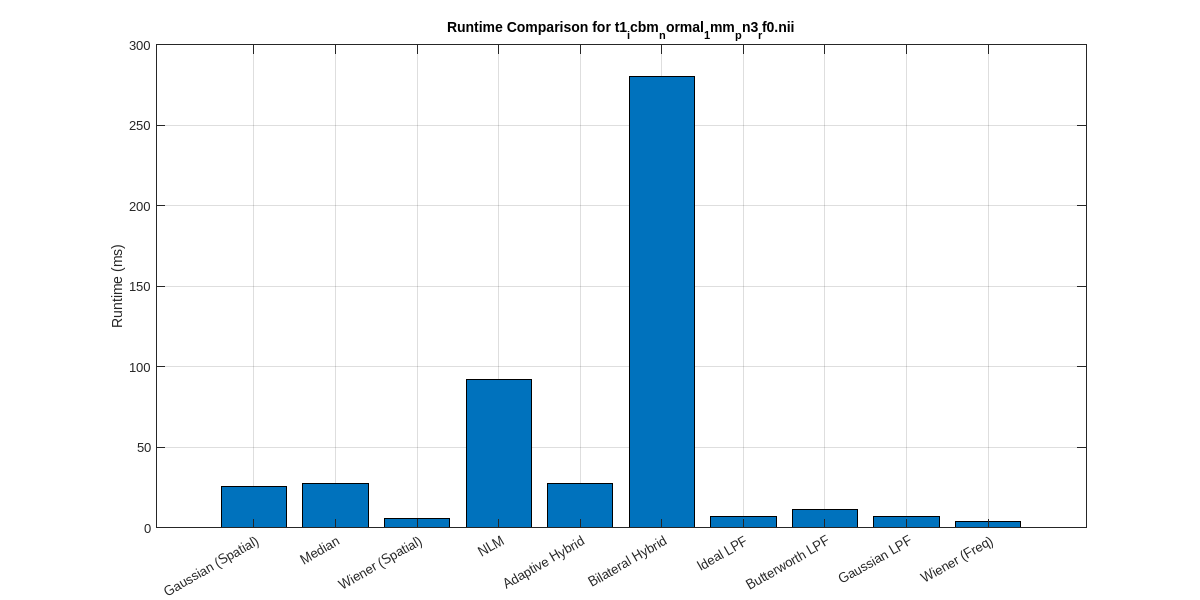

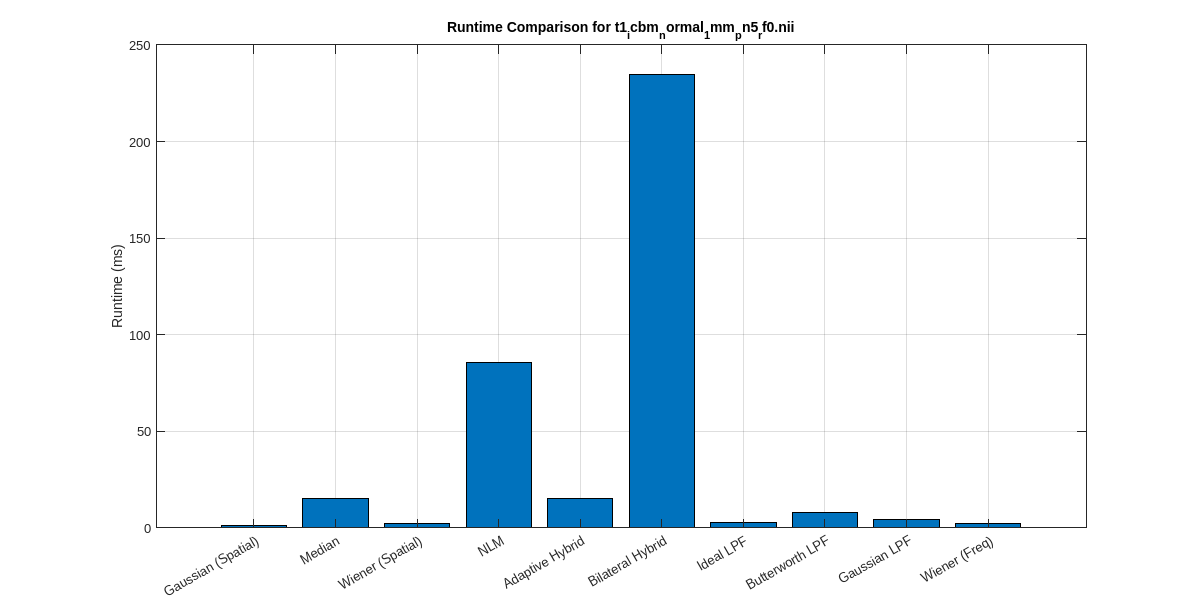

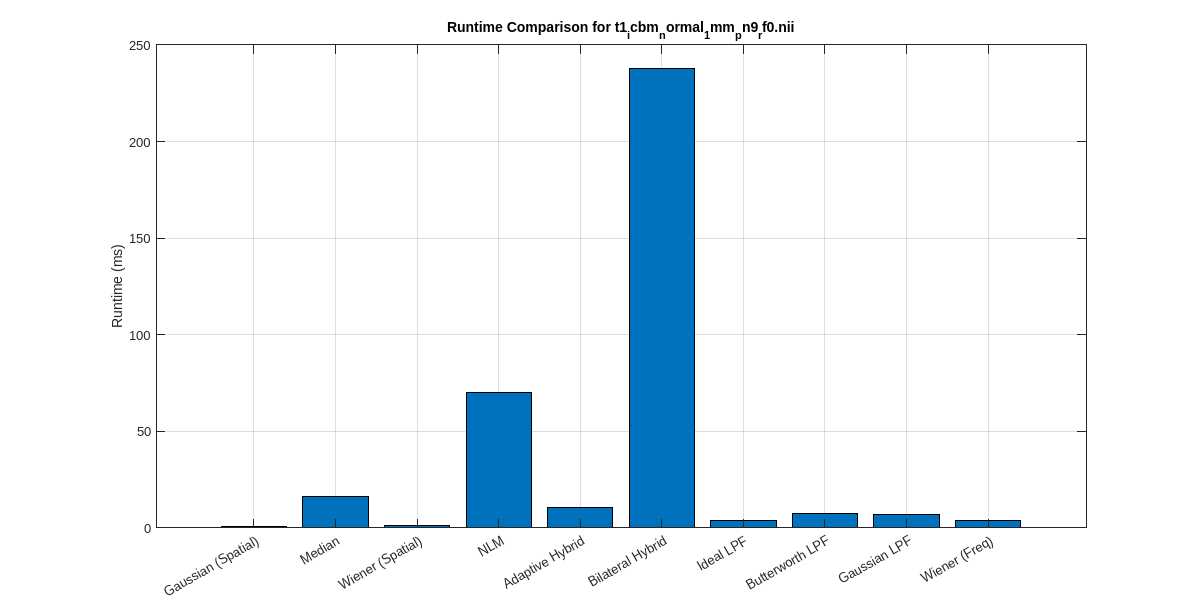

% BAR PLOT PER NOISE LEVEL

uniqueNoise = unique(T5.NoiseFile);

for n = 1:length(uniqueNoise)

    tbl = T5(strcmp(T5.NoiseFile, uniqueNoise(n)), :);

    figure('Position',[200 200 1200 600]);
    bar(tbl.Runtime_ms);
    set(gca, 'XTickLabel', tbl.Filter, 'XTickLabelRotation', 30);
    ylabel("Runtime (ms)");

    title("Runtime Comparison for " + uniqueNoise(n));
    grid on;

    fname = erase(uniqueNoise(n), ".nii");
    saveas(gcf, fullfile(outDir, 'figures', 'phase5', fname + "_runtime_plot.png"));

end